# Visión por Computador - Sessió 10

    Ferran Velasco Olivera

    Joaquín Gómez Sánchez

Hem provat amb diferents valors de N (número de descriptors de fourier) per representar els vectors de característiques de les imatges. Amb cada un d'aquests hem entrenat models amb diferents clasificadors (Tree, SVM i KNN) per veure quins donen millors resultats en cada cas. 

N = 10

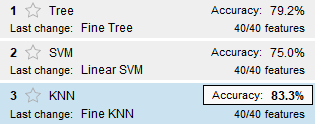

N = 30

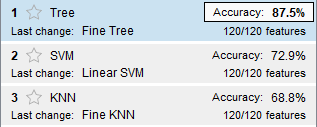

N = 80

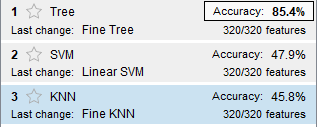

N = 150

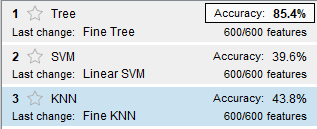

Podem concloure que hi ha un clar compromís entre la quantitat de descriptors que utilitzem i els mètodes empresos. En augmentar el número de descriptors som capaços de diferenciar fulles que amb menys descriptors s'assemblen massa, però en contrapunt l'augment excessiu del nombre de descriptors augmenta també la complexitat dels models, fent que alguns tendeixin a funcionar pitjor. 

D'aqui podem extreure que realment el que defineix la veritable forma de la fulla de l'arbre són els primers descriptors, ja que són els que defineixen els grans rasgos de la fulla. 

Si observem la matriu de confusió del millor resultat obtingut (Tree, 30 descriptors):

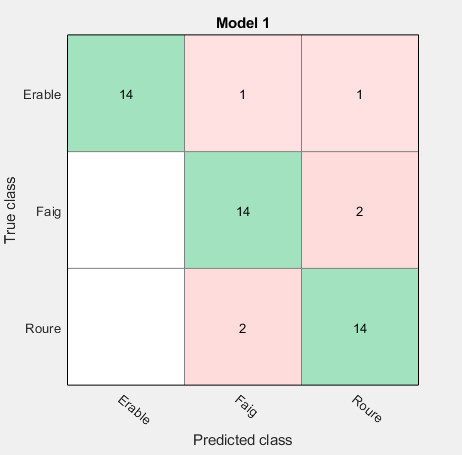

Observem que on es produeixen més errors és entre el Faig i el Roure. Això és degut a que a grans rasgos, les fullen tenen una forma més semblant que no pas el Erable, que té una fulla amb una forma molt més distinguida. 

## Extreure contorns i descriptors de fouriers

Prova d'extracció de contorns i descriptors de fouriers amb una determinada imatge. 

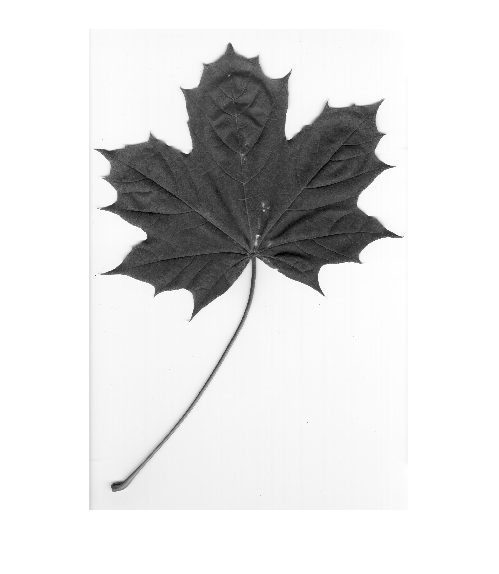

im = rgb2gray(imread("Erable\l2nr002.jpg"));
imshow(im)

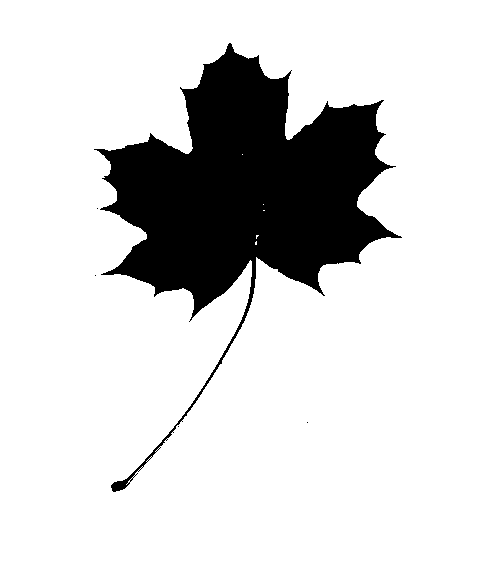

bw=im2bw(im, graythresh(im));
imshow(bw)

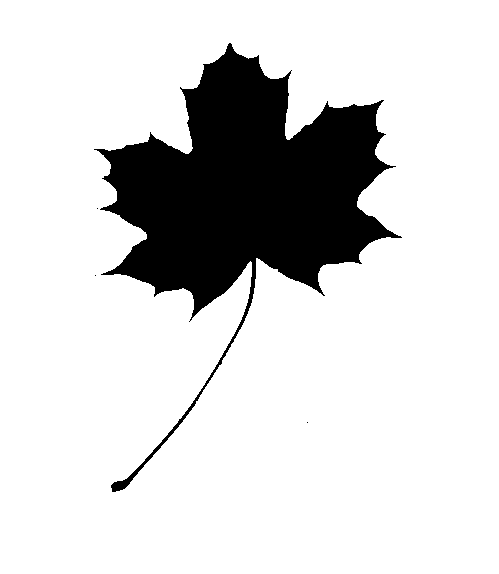

bg = imopen(bw,strel('disk',10));
imshow(bg)

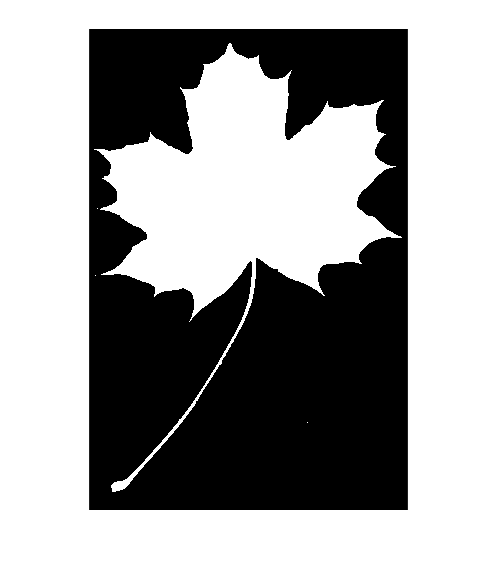

comp = imcomplement(bg);
imshow(comp)

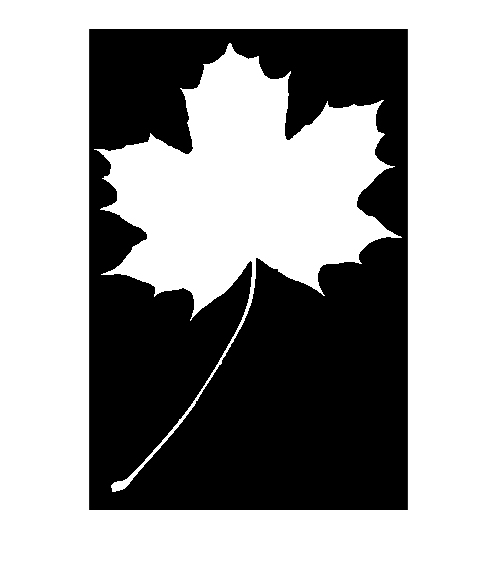

closed = imopen(comp, strel('disk',3));
imshow(closed)

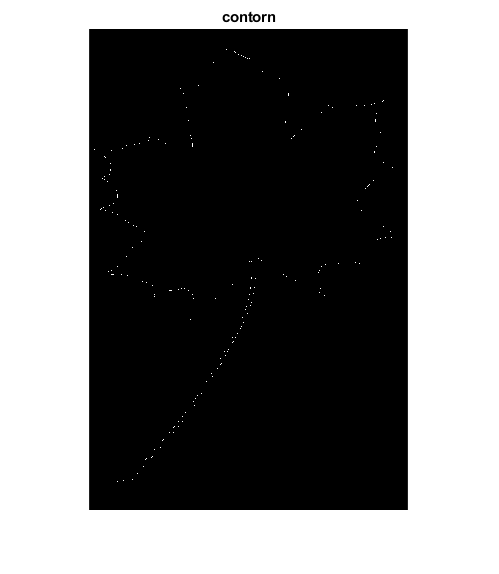


% obtenim el contorn
ero=imerode(closed,strel('disk',1));
cont=xor(ero,closed);
figure,imshow(cont), title('contorn')

% no es pot apreciar a simple vista, però el contorn és tancat

% descriptors de fourier
[fila col] = find(closed,1); % Busquem el primer píxel
B = bwtraceboundary(closed,[fila col],'E') %direccio est a l'atzar

B =    960    43
   960    44
   960    45
   960    46
   960    47
   960    48
   960    49
   960    50
   960    51
   960    52


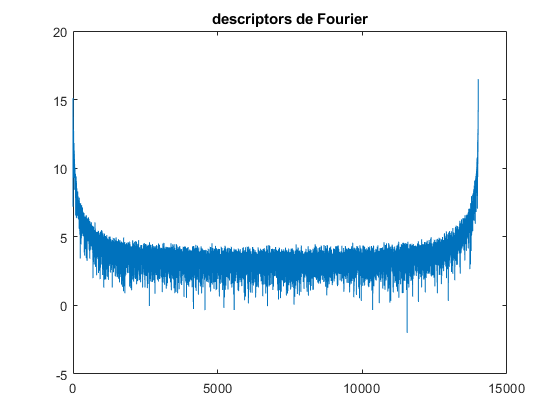


% centrem coordenades
mig=mean(B);
B(:,1)=B(:,1)-mig(1);
B(:,2)=B(:,2)-mig(2);

% Convertim les coordenades a complexes
s= B(:,1) + i*B(:,2);

% Cal que la dimensio del vector sigui parell
[mida bobo]=size(B);
if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
end

% Calculem la Fast Fourier Transform
z=fft(s);

% ho displaiem logaritmic perque no es veu res
figure,plot(log(abs(z))), title ('descriptors de Fourier')


N=30; % agafem N descriptors
tmp=z;
tmp(N+1:end-N)=0;

% a z tenim els N descriptors de fourier
z = tmp;


vec = 	1.0e+07 *

  -0.0001 - 0.0001i
  -0.0413 + 0.3631i
  -0.1823 - 0.2921i
   0.2718 + 0.0277i
  -0.0674 + 0.1186i
  -0.0191 - 0.1064i
  -0.0008 - 0.0793i
  -0.0261 + 0.0177i
  -0.0075 - 0.0116i
   0.0061 - 0.0323i


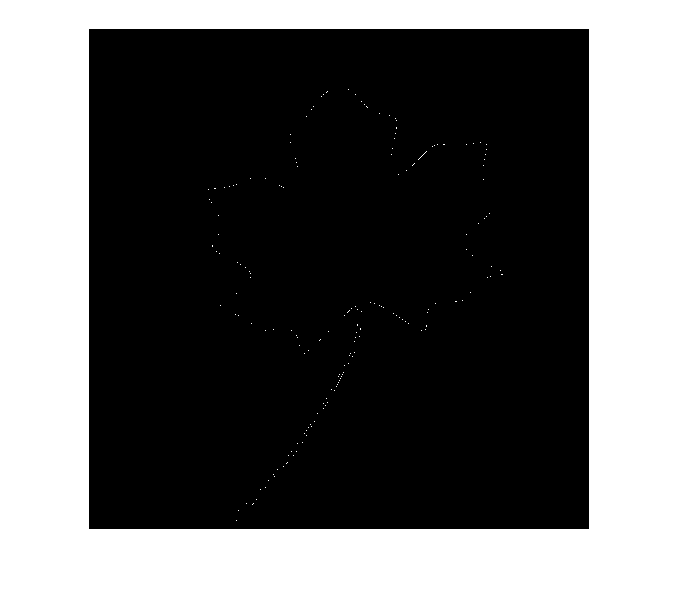

% Tornem al pla imatge a partir de l’espectre modificat
ss2=ifft(tmp);

% Les coordenades resultants poden sortir del rang de la imatge original
% Creo una imatge més gran per a que les coordenades no s'em surtin de mare
mida=4000;
files= round(real(ss2)+mida/2);
cols=round(imag(ss2)+mida/2);
aux=logical(zeros(mida));
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux)


% vector de característiques
vec = cat(1, tmp(1:N), tmp(end-N+1:end))

## Experimentació

N = 30
table1 = obtainImageSet('./Roure', '*.jpg', false, N);
table2 = obtainImageSet('./Faig', '*.jpg', false, N);
table3 = obtainImageSet('./Erable', '*.jpg', false, N);
newtable = vertcat(table1, table2, table3)

## Funcions

function table = obtainImageSet(dirBase, format, selector, N)
    % Get specific team (folder)
    d = '';
    if (selector)
        d = uigetdir(pwd, dirBase);
    else
        d = dirBase;
    end

    files = dir(fullfile(d, format));
    [rows cols] = size(files);

    for i = 1:rows
        [num ext] = split(files(i).name, '.');
        files(i).sort = str2num(num{1});
    end
    
    images = cell(1,rows);
    for i=1:rows
        image_file = imread(strcat(files(i).folder, '/', files(i).name));
        images{i} = image_file;
    end
    
    table = zeros(rows, N*4);
    for i = 1:rows
        table(i, :) = vectorDeCaracteristiques(images{i}, N).';
    end
    
    table = array2table(table);
    folders = split(files(i).folder, '\');
    table.class = repmat(folders(end), rows, 1);
end
function vec = vectorDeCaracteristiques(im, N)
    % imatge en escala de grisos
    im = rgb2gray(im);
    % binarització
    bw=im2bw(im, graythresh(im));
    bg = imopen(bw,strel('disk',10));
    comp = imcomplement(bg);
    closed = imopen(comp, strel('disk',3));
    ero=imerode(closed,strel('disk',1));
    cont=xor(ero,closed);
    [fila col] = find(closed,1); % Busquem el primer píxel
    B = bwtraceboundary(closed,[fila col],'E');
    
    % centrem coordenades
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    
    % Convertim les coordenades a complexes
    s= B(:,1) + i*B(:,2);
    
    % Cal que la dimensio del vector sigui parell
    [mida bobo]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:); %dupliquem l'ultim
        mida=mida+1;
    end
    
    % Calculem la Fast Fourier Transform
    z=fft(s);
    
    % agafem N descriptors
    tmp=z;
    tmp(N+1:end-N)=0;
    
    % vector de característiques
    vec = cat(1, tmp(1:N), tmp(end-N+1:end));
    
    [n m] = size(vec);
    
    aux = zeros(n*2, 1);
    
    for j=1:n
        complexNum = vec(j, 1);
        aux(j, 1) = real(complexNum);
        aux(n+j, 1) = imag(complexNum);
    end
    vec = aux;
end